% Code used to solve 
% numerically the parameters of the kinetic model.


Path="../../DataFiles\DPAPtOEP\Toluene\Kinetics\";
Path=""

Path = ""

FileName="DPA_10uM_Ptx535m435_g10us_d550.csv";
Steps=2;
%Data=table2array(readtable(strcat(Path,FileName)));
Data = table2array(readtable(FileName))

Data =    -0.0001   -0.0011
   -0.0001   -0.0011
   -0.0001   -0.0010
   -0.0001   -0.0011
   -0.0001   -0.0012
   -0.0001   -0.0012
   -0.0001   -0.0011
   -0.0001   -0.0011
   -0.0001   -0.0012
   -0.0001   -0.0012


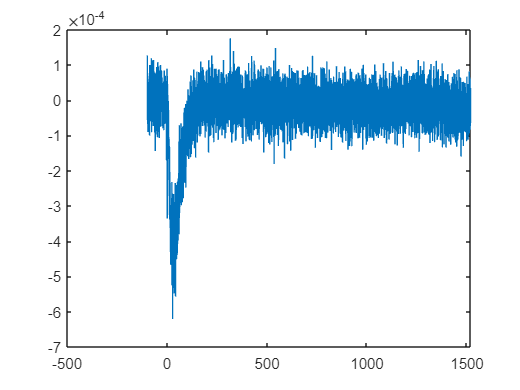

X=Data(:,1)*10^6;                   %Multiplying to change into us
Y=Data(:,2)-mean(Data(1:30,2));     %Leveling the y-data.
Y=decimate(Y,Steps);                %Decimate is a function that shortens the dataset.
X=decimate(X,Steps);
plot(X,Y)

BestVal = 1.0e+04 *

    0.0062    2.2950    4.6428   10.0000


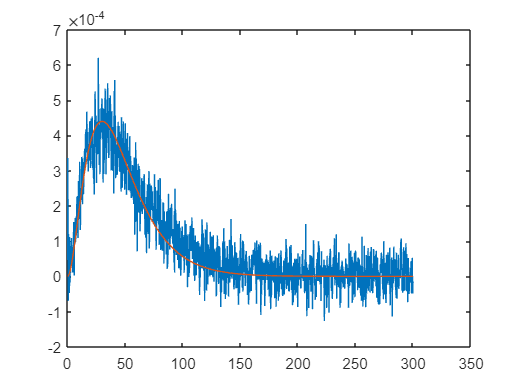

NotWorking = 0

Error = 3.3565e-04



StartIndex=0;
StopIndex=300;
Repetitions=5;
LowerLimit=[0,0,0,0];
UpperLimit=[100,100,100,100]/1000;
OwnParam=[];
DataAdaptation(Path,FileName,Steps,StartIndex,StopIndex,Repetitions,LowerLimit,UpperLimit,OwnParam)